# Repaso Quiz 1

### 05/09/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre el primer Quiz*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

*Notas frente al uso de los métodos:*

#### *        Métodos de una variable*

`    [c, err, n] = bisect(Function, Num1, Num2, Tol), `Método de bisección.

            - Function funcion definida @

            - Num1 y Num2 son los extremos del intervalo

            - Tol Es la tolerancia definida a la iteración

            - c es la aproximación obtenida por el método

            - err Error asociado a la iteración

            - n Pasos realizados para alcanzar la tolerancia

`    [p, k, err, P] = fixpt(g, p0, tol, max1), `Método de punto fijo.

            - g funcion creada con @

            - p0 es el supuesto inicial para el punto fijo

            - tol es la tolerancia

            - max1 es el numero maximo de iteraciones

            - p es la aproximacion del punto fijo

            - k es el numero de iteraciones realizadas

            - err es el error en la aproximacion

            - P' contiene la secuencia {pn}

`    [p, err, k, yc] = newton(f, df, p0, delta, epsilon, max1), `Método de Newton.

            - f funcion creada con @

            - df funcion derivada creada con @

            - p0 es la aproximacion inicial a cero de  f

            - delta es la tolerancia para  p0

            - epsilon es la tolerancia para los valores de la funcion  y

            - max1 es el numero maximo de iteraciones

            - p0 es la aproximacion de Newton-Raphson hacia cero

            - err es el error estimado para  p0

            - k es el numero de iteraciones

            - y es el valor de la funcion  f(p0)

`    [p, err, k, yc] = newton(f, df, d2f, p0, delta, epsilon, max1), `Método de Newton modificado.

            - f funcion creada con @

            - df primera derivada, funcion creada con @

            - d2f segunda derivada, funcion creada con @

            - p0 es la aproximacion inicial a cero de  f

            - delta es la tolerancia para  p0

            - epsilon es la tolerancia para los valores de la funcion  y

            - max1 es el numero maximo de iteraciones

            - p0 es la aproximacion de Newton-Raphson hacia cero

            - err es el error estimado para  p0

            - k es el numero de iteraciones

            - y es el valor de la funcion  f(p0)

*Frente a la definición del método de Newton acelerado, recordemos que este puede ser invocado usando el método de Newton y agrendando la multiplicidad de la raiz a hallar en la definición de la función o en la definición de la derivada de la función, tal como se indica:*

$x_{k+1} =x_k -M\frac{\;f\left(x_k \right)}{f^{\prime } \left(x_k \right)}$ : Definimos entonces $f\left(x_k \right):=M\;f\left(x\right)\;|\;f^{\prime } \left(x_k \right):=\frac{f^{\prime } \left(x\right)}{M}$.

#### *        Métodos de sistemas de ecuaciones*

`    X = jacobi(A, B, P, delta, max1), `Método de Jacobi.

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; los supuestos iniciales

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

            - X es una matriz  N x 1: la aproximacion de jacobi a

                la solucion de  AX = B

`    X = gseid(A, B, P, delta, max1), `Método de Gauss - Seidel.

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; el supuesto inicial

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

            - X es una matriz  N x 1: la aproximacion de gauss-seidel a

                la solucion de  AX = B

`    Y = sor(A, B, P, w, delta, max1), `Método de SOR

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; el supuesto inicial

            - w parametro de sobrerelajacion (0<w<2)

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

             - Y es una matriz  N x 1: la aproximacion de SOR a

                la solucion de  AX = B

`    P = newdim (F, JF, P, delta, epsilon, max1), `Método de Newton

            - F funcion del sistema creada con @

            - JF matriz jacobiana, funcion creada con @

            - P es la aproximacion inicial a la solucion

            - delta es la tolerancia para  P

            - epsilon es la tolerancia para  F(P)

            - max1 es el numero maximo de iteraciones

            - P es la aproximacion a la solucion

            - iter es el numero de iteraciones realizadas

            - err es el error estimado para  P

Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.

### Algunos problemas de repaso

Desarrollaremos algunos problemas que hemos discutido a lo largo de estas primeras semanas, y materiales que me compartieron para ver ejemplos tipicos de material que puede resultar bastante util.

`Importante: Los repasos solo los realizo en vivo, NO subo la solución en el cuaderno, de ser posible solo encontrarán el material en video.`

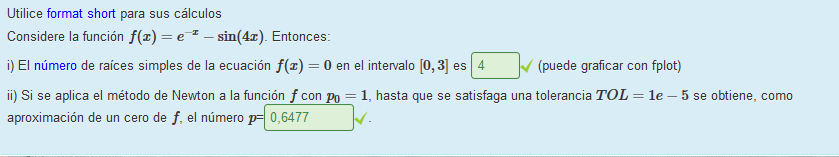

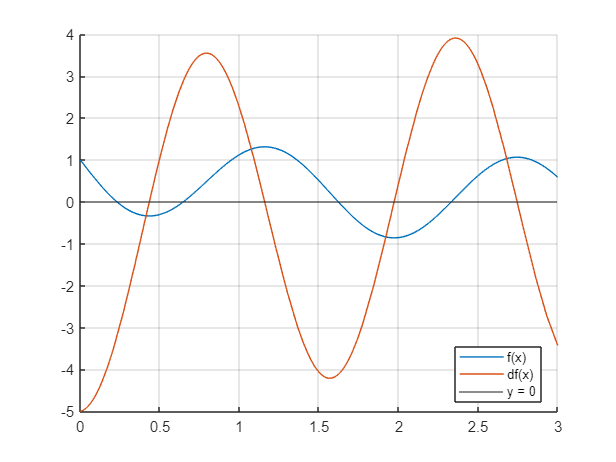

clear

syms f(x)

f(x) = exp(-x) - sin(4*x);
df(x) = diff(f, x);

clf('reset')
hold on
fplot(f, [0, 3], 'DisplayName', 'f(x)')
fplot(df, [0, 3], 'DisplayName', 'df(x)')
yline(0, 'DisplayName', 'y = 0')
grid on
legend('Location','best')
hold off

help newton

  Entrada - f funcion creada con @
          - df funcion derivada creada con @
          - p0 es la aproximacion inicial a cero de  f
 	      - delta es la tolerancia para  p0
 	      - epsilon es la tolerancia para los valores de la funcion  y
 	      - max1 es el numero maximo de iteraciones
  Salida  - p0 es la aproximacion de Newton-Raphson hacia cero
 	      - err es el error estimado para  p0
 	      - k es el numero de iteraciones
 	      - y es el valor de la funcion  f(p0)



p0 = 1;
f = matlabFunction(f); df = matlabFunction(df);

p = newton(f, df, p0, 1e-5, 1e-5, 100)

p = 0.6477

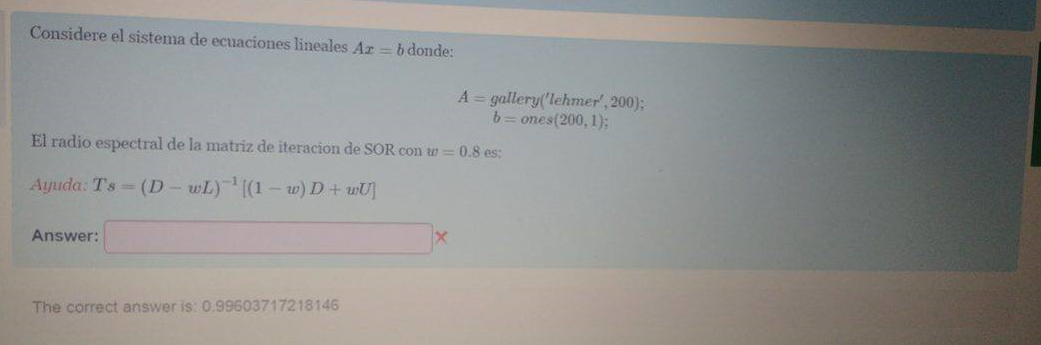

clear

format long

A = gallery('lehmer', 200);
b = ones(200, 1);

w = .8;
D = diag(diag(A)); L = -tril(A, -1); U = -triu(A, 1);
Tw = (D - w*L) \ ((1 - w) * D + w *U);

ratio = norm(eigs(Tw), 'inf'), ratio = max(abs(eigs(Tw)))

ratio =    NaN


ratio =    0.996037172183970


clear

format long

A = gallery('lehmer', 200);
b = ones(200, 1);

[~] = Jac_GS(A, .8);

Radio Espectral


ratioTJ =      1.082515969048929e+02


ratioTGS =    0.992738642765761


ratioTw =    0.996037172176857


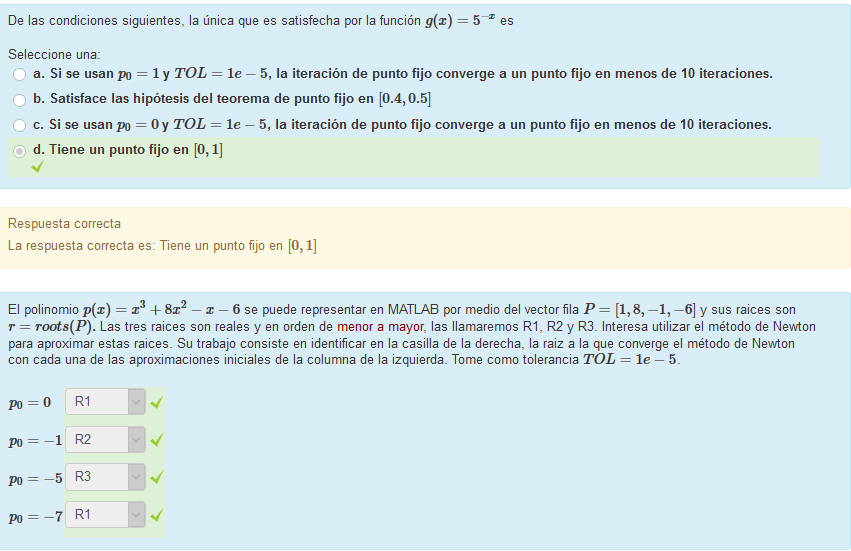

format short
clear

f = @(x) x.^3 + 8*x.^2 - x - 6;
P = [1 8 -1 -6];

dP = polyder(P);
df = @(x) polyval(dP, x);

raices = roots(P);
R = sort(raices)

R =    -8.0315
   -0.8487
    0.8802


c1 = newton(f, df, 0, 1e-5, 1e-5, 100)

c1 = -8.0315

c2 = newton(f, df, -1, 1e-5, 1e-5, 100)

c2 = -0.8487

c3 = newton(f, df, -5, 1e-5, 1e-5, 100)

c3 = 0.8802

c4 = newton(f, df, -7, 1e-5, 1e-5, 100)

c4 = -8.0315

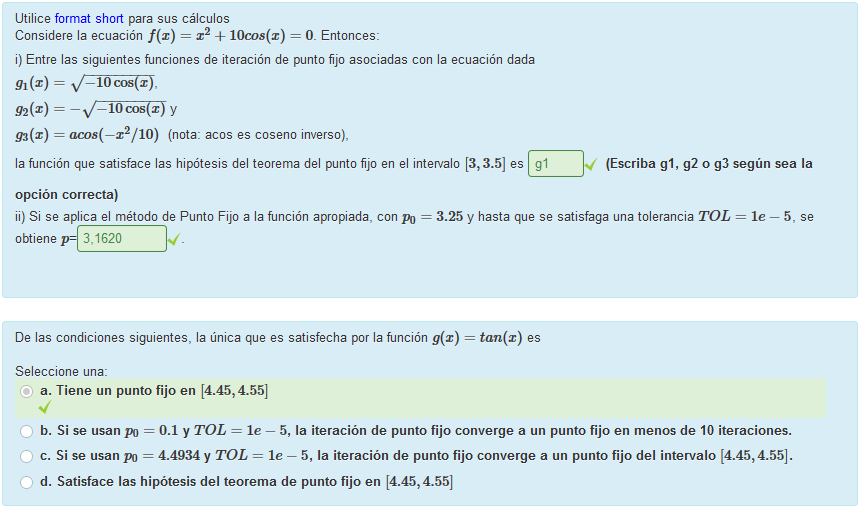

clear

syms g(x) [1 3]

'fixpt' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\lujan\Documents\UN\UN\Resources
    C:\Users\lujan\Documents\UN\UN\Resources\Alejo's Resources

Change the MATLAB current folder or add its folder to the MATLAB path.


g1(x) = sqrt(-10*cos(x));
g2(x) = -g1(x);
g3(x) = acos(-x^2 / 10);

clf('reset')
hold on
fplot(g1, [3, 3.5], 'DisplayName', 'g_1(x)')
fplot(g3, [3, 3.5], 'DisplayName', 'g_3(x)')
fplot(x, [3, 3.5], 'DisplayName', 'y = x')
grid on
legend('Location','best')
hold off
g1 = matlabFunction(g1);
c = fixpt(g1, 3.25, 1e-5, 100)
clf('reset')
hold on
fplot(g1, [3, 3.5], 'DisplayName', 'g_1(x)')
fplot(g3, [3, 3.5], 'DisplayName', 'g_3(x)')

Radio Espectral


ratioTJ = 0.4233

ratioTGS = 0.2083

ratioTw = 0.2083

fplot(x, [3, 3.5], 'DisplayName', 'y = x')

ans = 0.7907

ans = 1.0417

ans = 1.6000

plot(c, g1(c), 'or', 'DisplayName', 'x = c')
grid on
legend('Location','best')
hold off

A =    (1,1)        4
   (2,1)       -1
   (1,2)       -1
   (2,2)        4
   (3,2)       -1
   (2,3)       -1
   (3,3)        4
   (4,3)       -1
   (3,4)       -1
   (4,4)        4


A =      4    -1     0     0
    -1     4    -1     0
     0    -1     4    -1
     0     0    -1     4


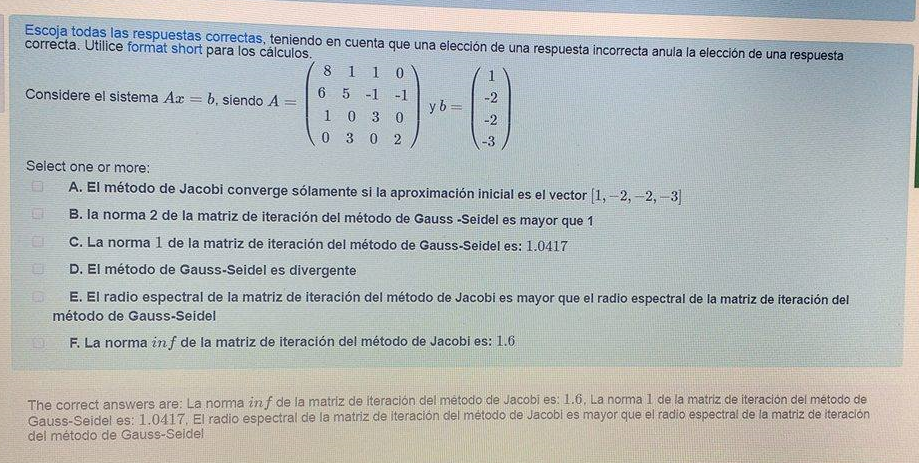

format short

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ =    0.404508497187474


ratioTGS =    0.163627124296868


ratioTw =    0.163627124296868


clear

ans =    0.500000000000000


ans =    0.332031250000000


k =      7


err =      1.610784910847593e-04


relerr =      7.463502719779531e-05


X =    0.488012567162514
   0.952136281877756
   1.320567355491221
   1.330141838872805


A = [8 1 1 0; 6 5 -1 -1; 1 0 3 0; 0 3 0 2]; b = [1 -2 -2 -3];

[TJ, TGS] = Jac_GS(A);
norm(TGS, 2), norm(TGS, 1), norm(TJ, 'inf')

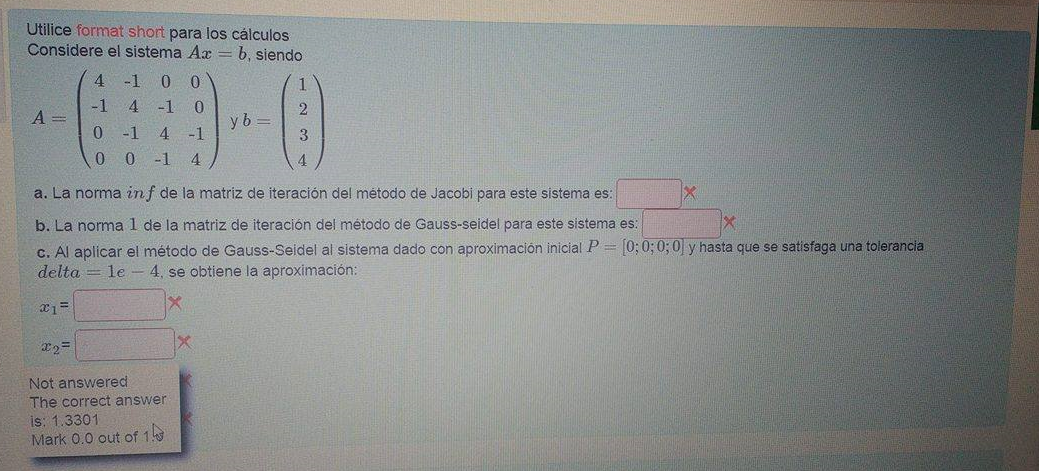

clear

A = gallery('tridiag', 4, -1, 4, -1), A = full(A), b = [1:4]';
[TJ, TGS] = Jac_GS(A);
norm(TJ, 'inf'), norm(TGS, 1)
X = gseid(A, b, zeros(size(b)), 1e-4, 100)

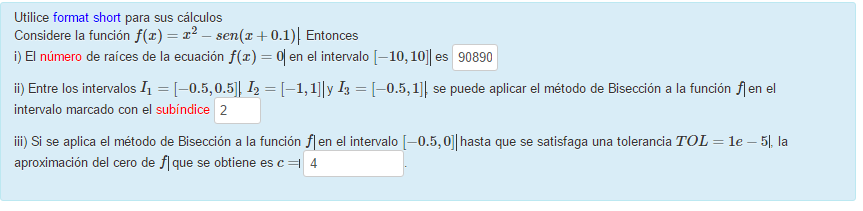

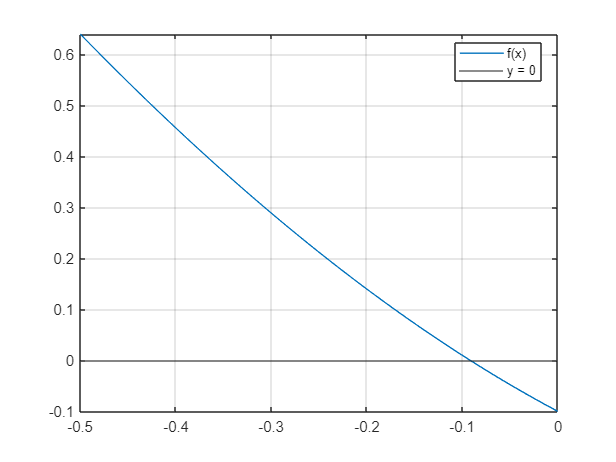

c = -0.0916

clear

syms f(x)

f(x) = x^2 - sin(x + .1);

clf('reset')
fplot(f, [-.5, 0], 'DisplayName', 'f(x)')
yline(0, 'DisplayName', 'y = 0')
grid on
legend('Location','best')
c = bisect(f, -.5, 0, 1e-5)